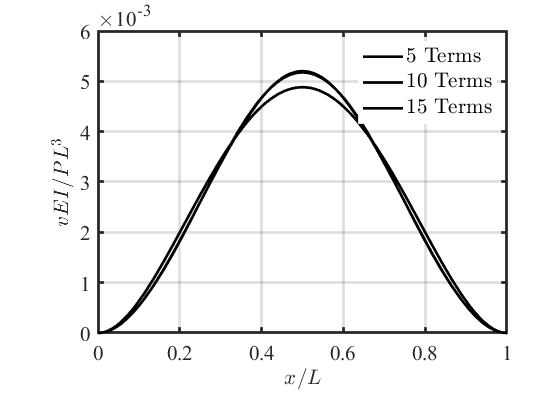

%       This code solves problem 5.57 from the text
%       A.F. Bower 'Solved Problems in Mechanics of Solids'  
%       CRC press, Baton Rouge, 2026
%
%       It was downloaded from
%       https://github.com/albower/Applied_Mechanics_of_Solids
clear all
close all
syms a x n_terms u 

figure1 = figure('NumberTitle','off','Name','Figure','Color',[1 1 1]);
axes3 = axes('Parent',figure1,...
    'Position',[0.175 0.207142857142857 0.73 0.717857142857145]);
    hold(axes3,'on');
    set(axes3,'FontName','Times','FontSize',16,...
        'LineWidth',2,'XGrid','on','YGrid','on',...
        'Box','On');

Linestyles = ['-','--','.-'];
count = 0;    
for n_terms=5:5:15
    clear eq
    a = sym('A',[n_terms,1]);
    u = 0;
    for i=1:n_terms
        u=u+a(i)*x^(i-1);
    end
    eq(1) = subs(u,x,0)==0;
    eq(2) = subs(diff(u,x),x,0)==0;
    eq(3) = subs(u,x,1)==0;
    eq(4) = subs(diff(u,x),x,1)==0;
    asol = struct2cell(solve(eq,[a(1),a(2),a(3),a(4)])); 
    for i=1:4
        u = subs(u,a(i),asol{i});
    end
    PI = int(1/2*diff(u,x,2)^2,x,[0,1] ) - subs(u,x,1/2);
    for i=5:n_terms
        eq(i)=diff(PI,a(i))==0;
    end
    if (n_terms>5)
      asol = struct2cell(solve(eq(5:n_terms),a(5:n_terms)));
      for i=5:n_terms
        u = subs(u,a(i),asol{i-4});
      end
    else
        asol = solve(eq(n_terms),a(n_terms));
        u = subs(u,a(n_terms),asol);
    end
    string = [num2str(n_terms) ' Terms'];
    count = count + 1;
    fplot(u,[0,1],'LineWidth',2,'color','k','LineStyle',Linestyles(count),'DisplayName',string)
    hold on
end
    ylabel({'$vEI/PL^3$' },'Interpreter','latex','FontSize',16);
    xlabel({'$x/L$'},'Interpreter','latex','FontSize',16);
    legend1 = legend(axes3,'show');
    set(legend1,...
        'FontSize',16,...
        'Interpreter','latex',...
        'FontName','Times New Roman',...
        'EdgeColor',[1 1 1]);